# Fourier Analysis of the fracture aperture distribution

The objective of this exercise is to implement an idea discussed with Nicola on Friday Feb 25th regarding analyzing fracture specific stiffness. Fracture specific stiffness is defined as "the average applied stressd divided by the average displacement across the fracture interface in excess of the displacement that would occur if the fracture were not present." (Hopkins et al. 1987).

The first thing to do is learn more about Fast-Fourier Transforms (FFT). I will be referring to (Cerna and Harvey, 2000) for guidance in understanding how to use FFT in analysing my data. I want to note that generally speaking, FFT is applied to time-series data i.e. data that change over time. For analysing fractures, we are interested in spacially variable data not time variant, so that will be a distict difference in using FFT.

## Example in Matlab documentation (modified for clarity).

The [fft](matlab:doc('fft')) documentation page has the example shown below. Here, the example has been edited for clarity. To access the original example run the following click [here](matlab:openExample('matlab/FFTOfNoisySignalExample')). 

Define the domain of the calculation

% the sampling frequency must be suffecient to sample the highest
% oscilation frequency. In this case, the max oscilation frequency is
% 12, so sampling frequency of 1000 samples per seconds is sufficient.
samplingFreq = 1000;                        % Sampling frequency    [samples/sec]             
samplingInterval = 1/samplingFreq;          % Sampling period       [sec/samples]
tf = 0.5;                                   % t final               [sec]
t = 0:samplingInterval:tf-samplingInterval; % Time vector           [sec]
nSamples = length(t)                        % Length of signal      [samples]

nSamples = 500

Form a signal containing a 50 Hz sinusoid of amplitude 0.7, a 120 Hz sinusoid of amplitude 1, and a DC shift (0 frequency amplitude) of 0.25;

S = 0.25 + 0.7 * sin(2*pi*50*t) + 1 * sin(2*pi*120*t);

ِCorrupt the signal with zero-mean white noise with a variance of 4.

X = S + 2 * randn(size(t));

Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal `X(t)`.

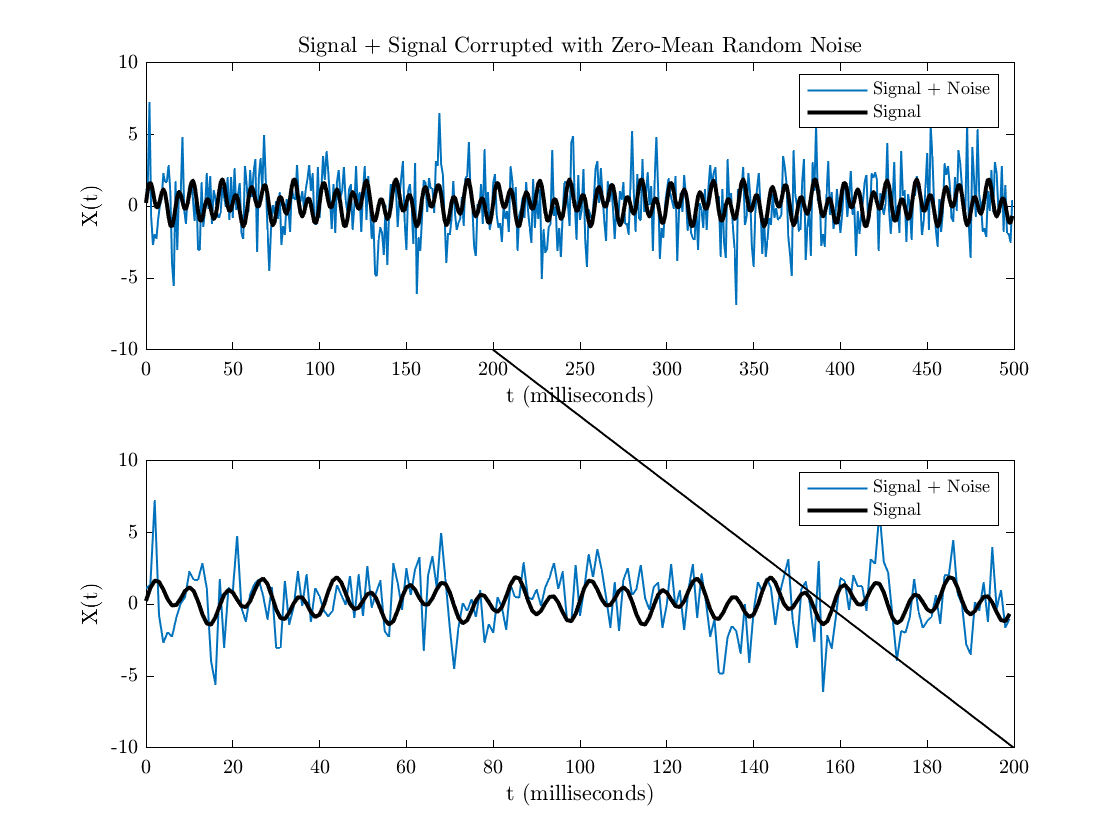

figure
subplot(2,1,1); 
plot(1000*t,X,'DisplayName','Signal + Noise'); hold on;
plot(1000*t,S,'k','DisplayName','Signal','LineWidth',2);
title('Signal + Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
legend
ax1 = gca;
nsamples = 200;
ax1.XTick = sort(unique([ax1.XTick,nsamples]));

subplot(2,1,2);
plot(1000*t(1:nsamples),X(1:nsamples),'DisplayName','Signal + Noise'); hold on;
plot(1000*t(1:nsamples),S(1:nsamples),'k','DisplayName','Signal','LineWidth',2);
%title('Signal + Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
legend
ax2 = gca; 
ax2.YLim = ax1.YLim;
% annotations
fig = gcf;

% plot a line between the subplots to relate them to one another
annotation(fig,'line',[ax1.Position(1)+ax1.Position(3)*(nsamples/length(t)) (ax2.Position(1)+ax2.Position(3))],[ax1.Position(2) ax2.Position(2)]);

Compute the Fourier transform of the signal. 

Y = fft(X);

Compute the two-sided spectrum `P2`. Then compute the single-sided spectrum `P1` based on `P2` and the even-valued signal length `L`. 

P2 = abs(Y/nSamples);       % we have to normalize by the signal length
P2(2:end) = 2*P2(2:end);    % we have to multiple all frequency amplitudes by 2 except for the zero frequency amplitude
% extract the single-sided spectrum from P2
P1 = P2(1:nSamples/2+1);

Define the frequency domain `f` and plot the single-sided amplitude spectrum `P1, and the double-sided amplitude spectrum P2.` The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise. On average, longer signals produce better frequency approximations.

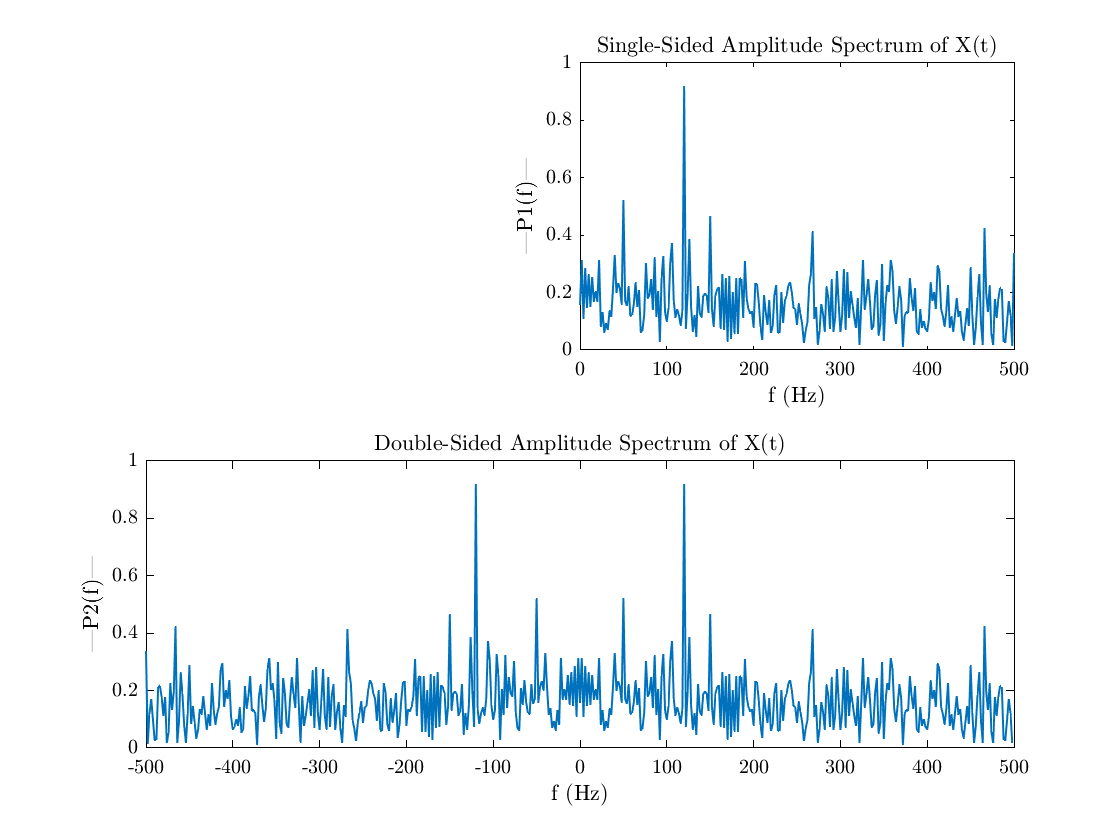

f = (0:(nSamples/2)) * (samplingFreq/nSamples);
fshift = (-nSamples/2:nSamples/2-1)*(samplingFreq/nSamples);

P2 = fftshift(P2);

figure
subplot(2,2,2);
plot(f,P1);
title('Single-Sided Amplitude Spectrum of X(t)');
xlabel('f (Hz)');
ylabel('|P1(f)|');
xlim([0 500]);
ax1 = gca; 

subplot(2,2,3:4);
plot(fshift,P2) 
title('Double-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P2(f)|')
ax2 = gca;
ax1.Position([1 3]) = [ax2.Position(1)+ax2.Position(3)/2, ax2.Position(3)/2];  

Now, zoom in to inspect the 0 frequency element in both plots

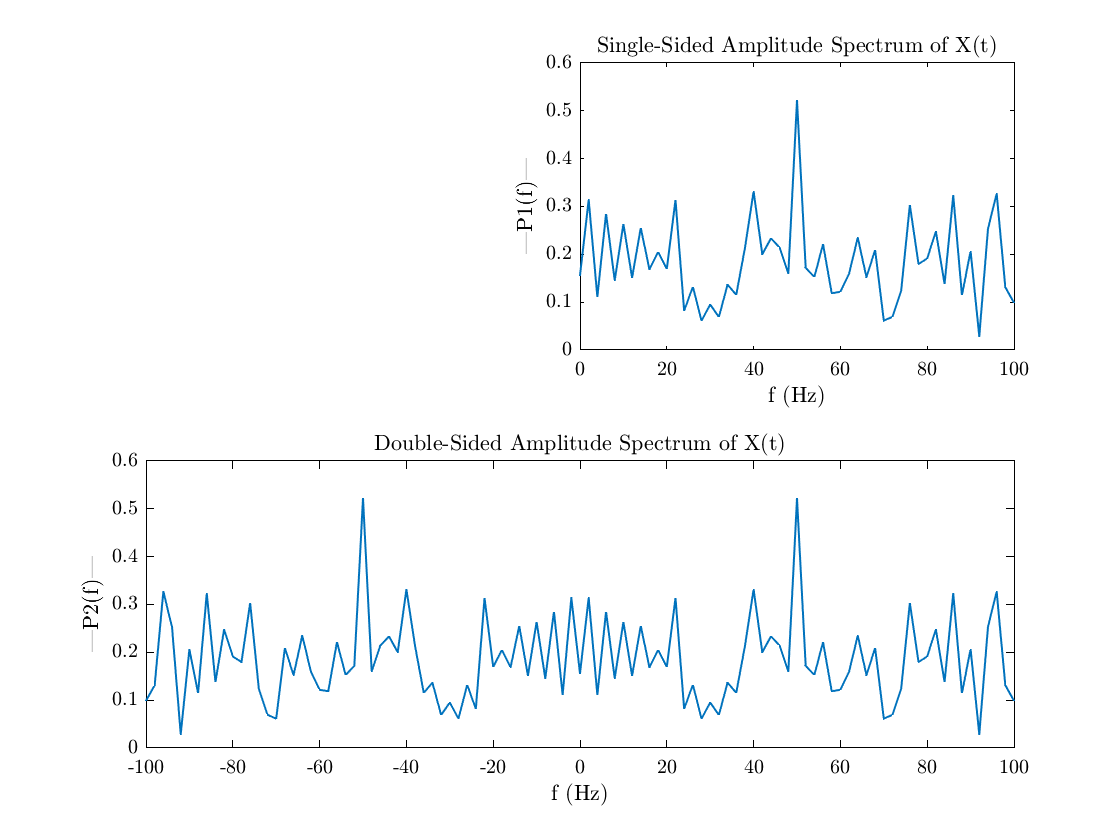

horizontalLim = 100;

figure
subplot(2,2,2);
plot(f,P1);
title('Single-Sided Amplitude Spectrum of X(t)');
xlabel('f (Hz)');
ylabel('|P1(f)|');
xlim([0 horizontalLim]);
ax1 = gca; 

subplot(2,2,3:4);
plot(fshift,P2) ;
title('Double-Sided Amplitude Spectrum of X(t)');
xlabel('f (Hz)');
ylabel('|P2(f)|');
xlim([-horizontalLim horizontalLim]);
ax2 = gca;
ax1.Position([1 3]) = [ax2.Position(1)+ax2.Position(3)/2, ax2.Position(3)/2];  

*Copyright 2012 The MathWorks, Inc.*

## Desconstructing the Matlab example for better understanding

The following [link](https://medium.com/analytics-vidhya/breaking-down-confusions-over-fast-fourier-transform-fft-1561a029b1ab) is useful in guiding through applyig `fft` 

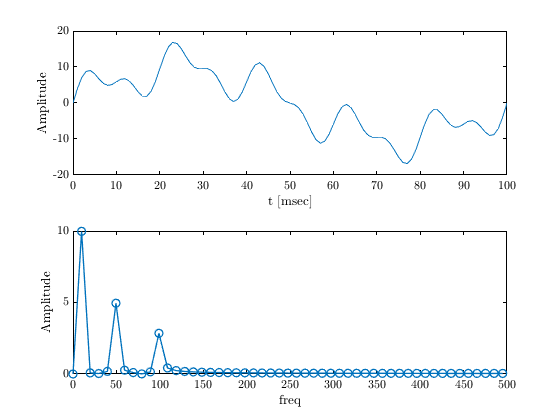

% consider a time series signal that is purely sinosoidal
freq = [10, 50, 100];
amp  = [10, 5, 3];
samplingFreq = 10*max(freq);         % sampling frequencye [sample/time]
samplingInterval = 1/samplingFreq;
tf = 0.1; 
t = 0:samplingInterval:tf;
y = @(t,f,A) A*sin(2*pi*f*t);

dc = 0; 
x = zeros(size(t));
for i = 1:length(freq)
    x = x + y(t,freq(i),amp(i));
end
% 0 freq (dc) shift
x = x + dc; 

figure
subplot(2,1,1);
plot(1000*t,x,'-')
xlabel('t [msec]');
ylabel('Amplitude')
%xlim([0 t(end)])

Y = fft(x);
nSamples = length(t);

% in the following, normalizing by the number of samples is simply part of
% the algorith. I did not look much further into it, and I don't think it
% matters too much
P2 = abs(Y/nSamples);

% computing the signle side band, or singles-sided spectrum, we take the
% first half of P2. Note that P2(1) is the DC or zero-frequencye componenet
P1 = P2(1:floor(nSamples/2)+1);

% since the first element of the P1 is the DC element, we multiple the rest
% by 2 which is equivalent to applying the Hilbert transform (based on the
% link above!)
P1(2:end) = 2*P1(2:end);
 
% to find the x-axis, we need to do the following. I need to study this
% further to better understand it.
freqFFT = (0:fix(nSamples/2))*(samplingFreq/nSamples);

subplot(2,1,2);
signalLength = length(t);
faxis = samplingFreq*(0:signalLength-1)/signalLength-signalLength/2;
plot(freqFFT,P1,'-o')
%xlim([freqFFT(1) freqFFT(end)]);
ylabel('Amplitude');
xlabel('freq');

## Generating an example siganl (this needs work, if not abandonment!)

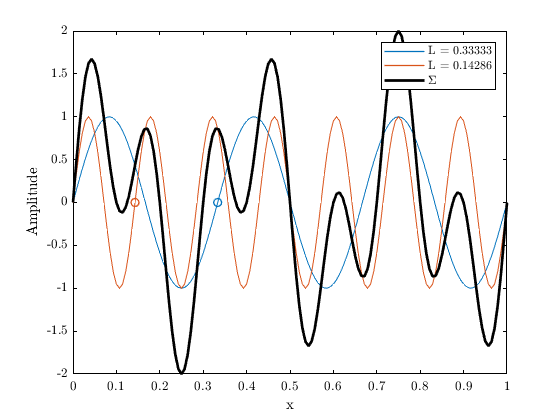

% defining the 1d spatial domain of interest

% I will come back to the following commented lines
%{
imageResolution     = 33.3e-3; % [mm/sample]
samplingFrequency   = 1/(imageResolution * 1000)
sampleNominalDiameter = 25; % [mm]
%}
k = [3 7];           % wave numbers
lambda = 1./k;             % wave lengths
samplingFreqX = 0.05*min(lambda);      % [length/sample] ~ "sampling period"
dX = 1/samplingFreqX;                  % [sample/length] ~ "sampling frequency"
x = 0:samplingFreqX:3*max(lambda);

phaseShifts = zeros(size(lambda)); %linspace(0,pi/2,length(lambda)); % phase


% computing the resultant signal and plotting it
f = zeros(size(x));
figure

% plotting the wave length markers
for i = 1:length(lambda)
    l = plot(lambda(i), 0,'o'); hold on;
    l.Annotation.LegendInformation.IconDisplayStyle = 'off';
end

% extracting the color imformation to match the following line plots
ax = gca;
lineColors = {ax.Children.Color};
% reverse the order of lineColors
lineColors = {lineColors{end:-1:1}};

% plotting the signals
for i = 1:length(lambda)
    tmp = sin(2*pi*k(i)*x+phaseShifts(i));
   f = f + tmp;
   plot(x,tmp,'DisplayName',['L = ',num2str(lambda(i))],'Color',lineColors{i});
end

% plotting signal combination
plot(x,f,'LineWidth',2,'Color','k','DisplayName','$\Sigma$');
legend
xlabel('x');
ylabel('Amplitude');

Computing the `fft` of $f(x)$

Y = fft(f)

Y =    0.0000 + 0.0000i   0.0115 - 0.5146i   0.0661 - 1.4814i   4.7230 -70.5531i  -0.0826 + 0.9240i   0.0518 - 0.4629i   0.3192 - 2.3738i  10.7840 -68.5820i  -0.7758 + 4.3061i  -0.4790 + 2.3564i  -0.3837 + 1.6936i  -0.3371 + 1.3478i  -0.3097 + 1.1306i  -0.2918 + 0.9790i  -0.2792 + 0.8660i  -0.2701 + 0.7777i  -0.2631 + 0.7064i  -0.2576 + 0.6473i  -0.2532 + 0.5972i  -0.2497 + 0.5541i  -0.2467 + 0.5166i  -0.2443 + 0.4834i  -0.2422 + 0.4539i  -0.2404 + 0.4273i  -0.2389 + 0.4033i  -0.2376 + 0.3814i  -0.2364 + 0.3614i  -0.2354 + 0.3429i  -0.2345 + 0.3258i  -0.2337 + 0.3098i  -0.2329 + 0.2950i  -0.2323 + 0.2811i  -0.2317 + 0.2680i  -0.2312 + 0.2556i  -0.2307 + 0.2439i  -0.2303 + 0.2329i  -0.2299 + 0.2223i  -0.2295 + 0.2123i  -0.2292 + 0.2027i  -0.2289 + 0.1935i  -0.2286 + 0.1847i  -0.2284 + 0.1763i  -0.2282 + 0.1681i  -0.2279 + 0.1602i  -0.2277 + 0.1526i  -0.2276 + 0.1453i  -0.2274 + 0.1381i  -0.2272 + 0.1312i  -0.2271 + 0.1245i  -0.2270 + 0.1179i


nSamples = length(f);
P2 = abs(Y/nSamples);
P1 = P2(1:nSamples/2+1);

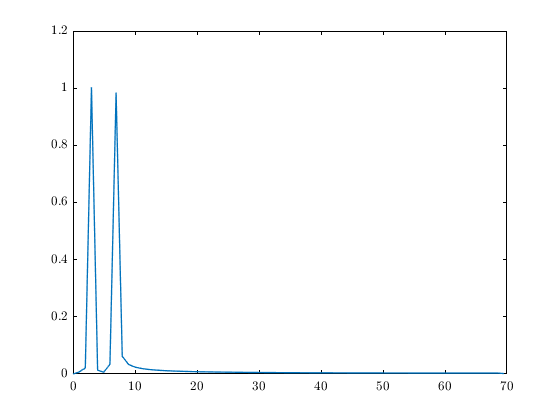

P1(2:end-1) = 2*P1(2:end-1);

K = dX*(0:(nSamples/2))/nSamples; % wavenumber (frequency)
figure
plot(K,P1)

# 2D FFT

Here we try to generate a 2D fft and see how it looks

umpermm = 1e3;                  % [micrometer / milimeter]
dx = 33.3 / umpermm;            % [mm]
samplingFreqX = 1/dx;    % [mm/sample]
dy = dx;
samplingFreqY = 1/dy;
xmax = 30;                        % [mm]
ymax = 10;                        % [mm]

X = 0:dx:xmax-dx;
nSampleX = length(X);

Y = 0:dy:ymax-dy;
nSampleY = length(Y);

[x,y] = meshgrid(X,Y);
originalSize = size(x);

deg = 0;
theta = 2*pi/180 * deg; 
B = [cos(theta)  sin(theta);
     -sin(theta) cos(theta)];
tmp = B*[x(:)';y(:)'];
x = reshape(tmp(1,:),originalSize);
y = reshape(tmp(2,:),originalSize);

lambdaX = 10;                    % [mm] the wavelength in the x-direction
freqX = 1/lambdaX

freqX = 0.1000

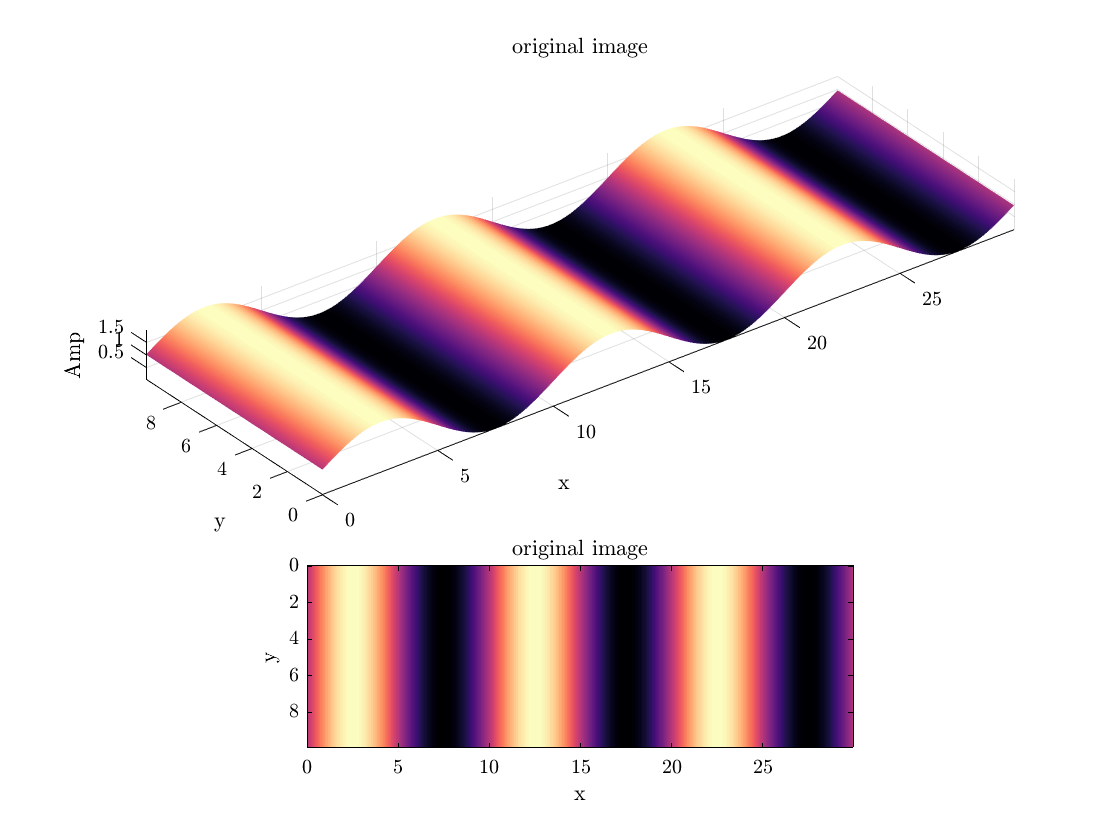

A = 1;
DC = 1; 
z = DC + A * sin(2*pi*x/lambdaX); 

figure
subplot(3,2,[1:4]);
surf(X,Y,z);
shading interp
axis image
%view([0.60 90.00]);
xlabel('x');
ylabel('y');
zlabel('Amp');
title('original image');
subplot(3,2,[5,6])
imagesc(X,Y,z);
%shading interp
axis image
%view([0.60 90.00]);
xlabel('x');
ylabel('y');
zlabel('Amp');
title('original image');

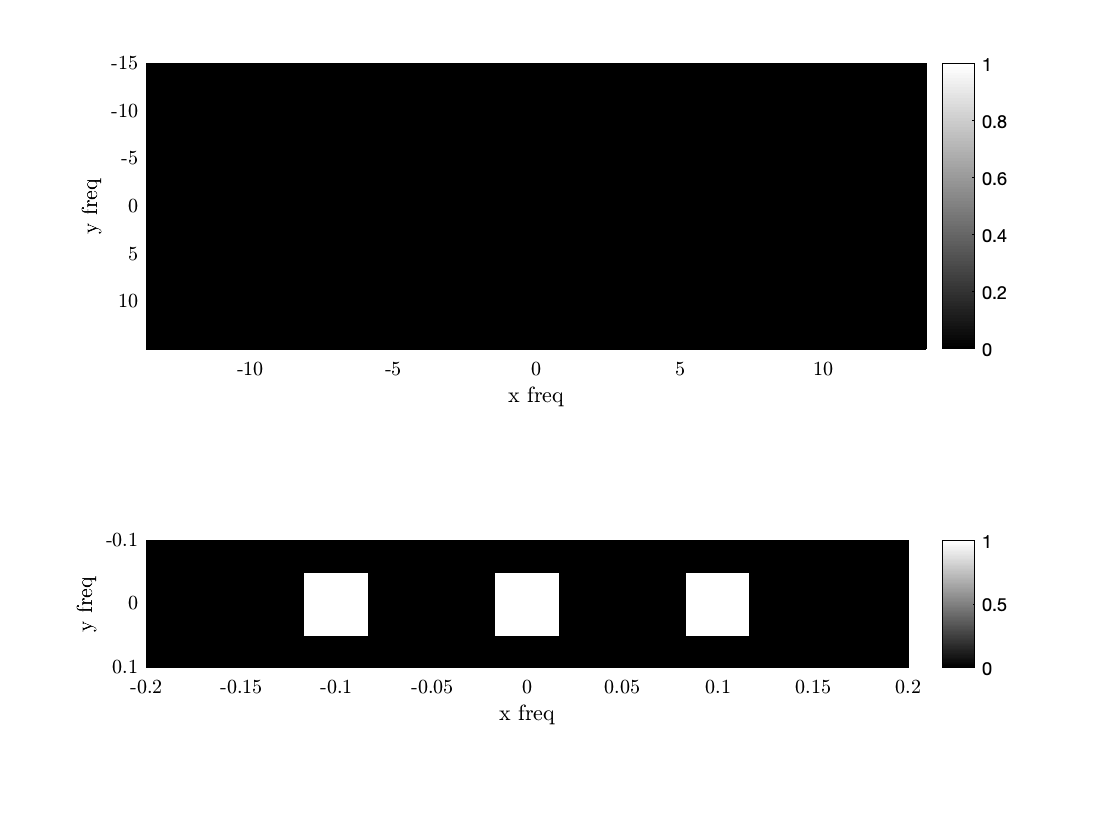

% zfft = fft2(z,2^nextpow2(length(Y)),2^nextpow2(length(X)));
zfft = fft2(z);
clear P2
P2 = abs(zfft*(1/nSampleX)*(1/nSampleY));

% extract the DC componenet (0-freq amplitude)
DC = P2(1,1);
% multiply everything by 2. Maybe this needs to be multiplied by 2^2 since
% it is a 2d image??
P2 = 2 * P2;
% reassign the DC componenet
P2(1,1) = DC;
% shift the DC component to the center of the image
P2centered = fftshift(P2); 

fshiftX = (-nSampleX/2:nSampleX/2-1)*(samplingFreqX/nSampleX);
fshiftY = (-nSampleY/2:nSampleY/2-1)*(samplingFreqY/nSampleY);

figure
subplot(2,1,1)
imagesc(fshiftX,fshiftY,P2centered);
shading flat;
ax = gca;
ax.CLim = [0 1]; colorbar
axis equal
colormap gray;
xlabel('x freq');
ylabel('y freq');
%xlim(freqX*[-2 2]);
%ylim(0.1*[-1 1]);
ax.DataAspectRatio = [1 nSampleX/nSampleY 1]; % this works only with the current configuration

subplot(2,1,2)
imagesc(fshiftX,fshiftY,P2centered);
shading flat;
ax = gca;
ax.CLim = [0 1]; colorbar
axis equal
colormap gray;
xlabel('x freq');
ylabel('y freq');
xlim(freqX*[-2 2]);
ylim(0.1*[-1 1]);
ax.DataAspectRatio = [1 nSampleX/nSampleY 1]; % this works only with the current configuration

# Side Notes

## Online University Physics book

In an attempt to understand the difference between amplitude and power, I found the following link that explains power very well: [https://openstax.org/books/university-physics-volume-1/pages/16-4-energy-and-power-of-a-wave#:~:text=The%20time%2Daveraged%20power%20of,by%20a%20factor%20of%20four.](https://openstax.org/books/university-physics-volume-1/pages/16-4-energy-and-power-of-a-wave#:~:text=The%20time%2Daveraged%20power%20of,by%20a%20factor%20of%20four.)

The link is part of an online text book on university physics.

# References

Cerna, M., and A. F. Harvey, 2000, The Fundamentals of FFT-Based Signal Analysis and Measurement: Application Note 041, National Instruments.  

Hopkins, D. L., N. G. W. Cook, and L. R. Myer, 1987, Fracture Stiffness And Aperture As A Function Of Applied Stress And Contact Geometry: , ARMA-87-0673.

Chuan-Zheng Lee (2017). *Signals and the frequency domain*. (pdf). Available from: <https://web.stanford.edu/class/archive/engr/engr40m.1178/slides/signals.pdf>. [Accessed 02/28/2022 ].